% I hate warnings 
warning off; 

% Create a DEM of some size 
sizeDEM = 100;
ZI = peaks(sizeDEM);

% Assert DEM
figure; clf; hold off; 
disp('DEM Model:')

DEM Model:


tic;
surf(ZI);
toc;

Elapsed time is 0.025544 seconds.


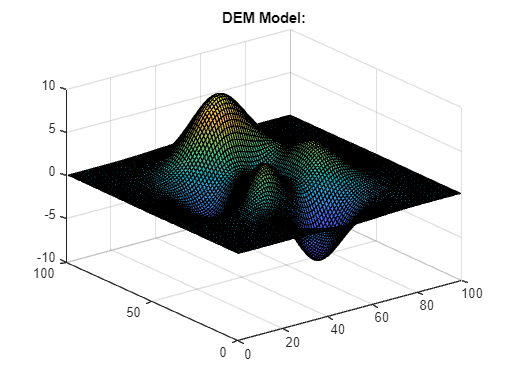

title('DEM Model:');

disp('-----');

-----


TIN with Tol = 0.1


Elapsed time is 0.017866 seconds.


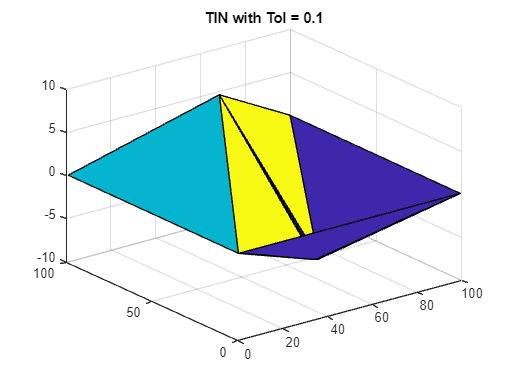

-----


TIN with Tol = 0.01


Elapsed time is 0.017449 seconds.


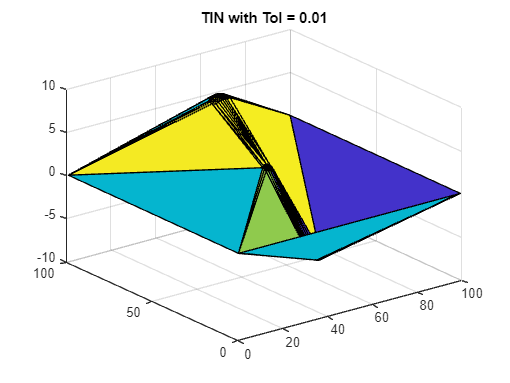

-----


TIN with Tol = 0.001


Elapsed time is 0.016664 seconds.


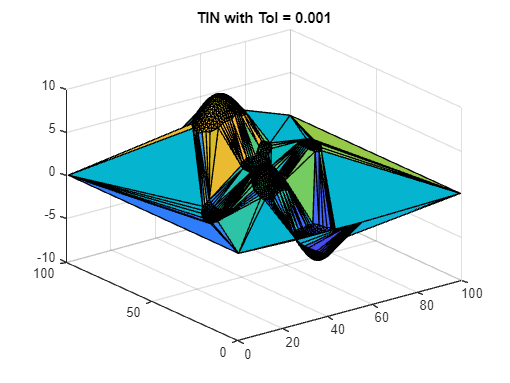

-----



% Create TINs of Different Tolerances
for i = 1:3

    % Iteratively Set Tolerance
    tol = 1*10^(-i);
    name = append('TIN with Tol = ', num2str(tol));
    disp(name);

    % Create Figure
    figure; clf; 

    % Find TIN model from DEM shown above
    [tri, x, y, z] = myTIN(ZI, tol);

    % Plot the TIN found 
    tic;
    trisurf(tri, x, y, z);
    toc;
    
    % Update Figure and Separate
    title(name);
    disp('-----');

end